# Image Denoising with Self-Adaptive ADMM (S-ADMM)

1. Load and Prepare Image

Loads the original image, converts it to grayscale, and normalizes it for processing.

`I` – reads the image from your computer.

`rgb2gray(I)` – converts color to grayscale.

`double(...)/255` – normalizes pixel values between 0 and 1.

`[m, n]` – image height and width.

Displays the clean grayscale image.

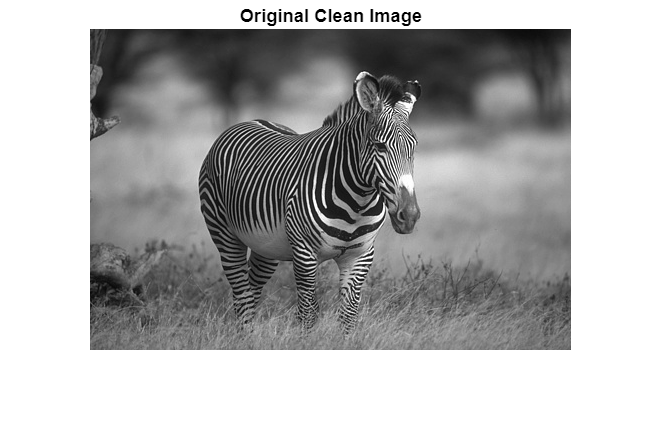

I = imread("C:\Users\Jignesh Sudheer\OneDrive\Desktop\mfcs3\bsd\bsd\130066.jpg"); % Set your file path
I_gray = double(rgb2gray(I)) / 255; % Convert to grayscale and normalize
[m, n] = size(I_gray);

figure;
imshow(I_gray, []); title('Original Clean Image');

2.Displays the noisy image for visual check.

`noisy_level` – controls how much noise is added.

`randn(m, n)` – creates Gaussian noise.

`D` – noisy version of the image (used as input to denoise).

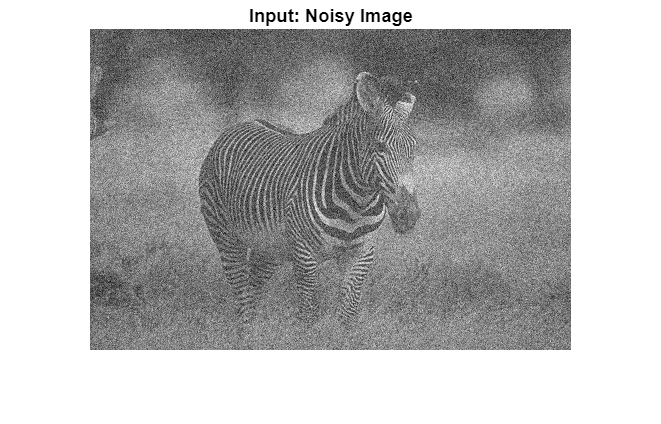

%% Add Synthetic Noise (optional)
noisy_level = 0.15;
rng(1);
noise = noisy_level * randn(m, n);
D = I_gray + noise; % Noisy image

figure;
imshow(D, []); title('Input: Noisy Image');

3. S-ADMM Denoising Parameters

`lambda` – sparsity weight (larger = smoother image).

`gamma0` – initial penalty parameter in ADMM.

`rho` – controls how much `gamma` adapts each iteration.

`maxIter` – maximum number of iterations.

`tol` – tolerance to stop early when convergence is reached.


%% S-ADMM Denoising Parameters
lambda = 0.1;      % Controls sparsity
gamma0 = 1.0;      % Initial penalty parameter
rho = 0.2;         % Adaptation sensitivity
maxIter = 100;     % Maximum iterations
tol = 1e-6;        % Convergence tolerance

4. This is the SVT (singular value thresholding) proximal operator for the nuclear norm. Given matrix `A` and threshold `tau`, it computes the SVD (`U*S*V'`), shrinks singular values by `tau` (setting negatives to zero), and reconstructs the low-rank matrix `Z`. In ADMM this is the closed-form update for the low-rank component. Performance note: `svd` is the heavy computation here; for large images you may want truncated or randomized SVD (`svds`, randomized SVD) to accelerate things.

%% Singular Value Thresholding (SVT)
function Z = svt(A, tau)
    [U, S, V] = svd(A, 'econ');
    s = diag(S);
    s_thresh = max(s - tau, 0);
    keep = s_thresh > 0;
    if ~any(keep)
        Z = zeros(size(A));
        return
    end
    U = U(:, keep);
    V = V(:, keep);
    Z = U * diag(s_thresh(keep)) * V';
end

5. The **ℓ₂,₁-norm** (L two, one norm) is defined as:


$$\|\mathbf{X}\|_{2,1} = \sum_{j=1}^{n} \sqrt{ \sum_{i=1}^{m} X_{ij}^2 }$$


It takes the L₂ norm (Euclidean norm) of each column, then sums all those norms.

This encourages *column sparsity* — entire columns of **X** tend to become zero.

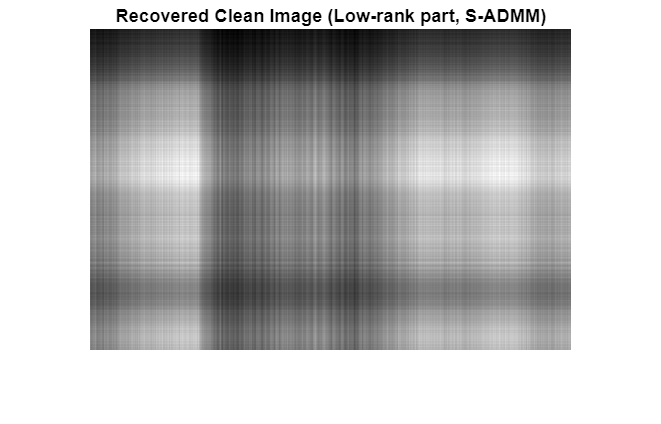

%% Column-wise l2,1 Shrinkage
function X = col_shrink_21(B, thresh)

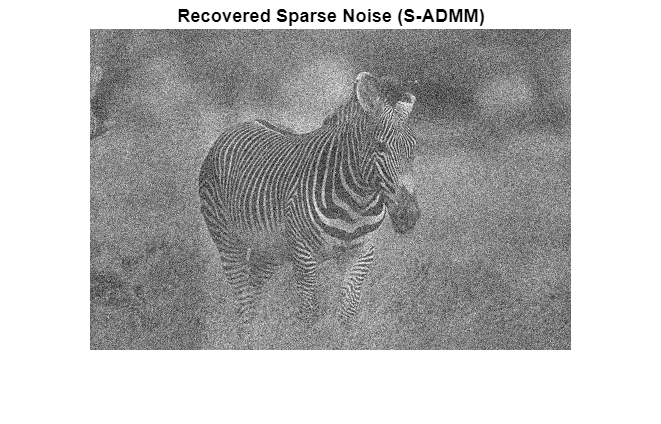

    norms = sqrt(sum(B.^2, 1));
    X = zeros(size(B));
    nz = norms > 0;
    factors = max(1 - thresh ./ (norms(nz) + eps), 0);

    X(:, nz) = B(:, nz) .* factors;
end

6. S-ADMM Function for Denoising (with gamma tracking)

`sadmm` – main Self-Adaptive ADMM loop.

Inputs: `D` (noisy image), `lambda`, `gamma0`, `rho`, `maxIter`, `tol`.

`Z` – low-rank image estimate (clean).

`X` – sparse noise estimate.

`Y` – dual variable in ADMM.

`gamma` – penalty parameter that adapts each iteration.

`hist.mse` – stores MSE each iteration.

`hist.gamma` – tracks how gamma changes.

Adaptive rule:

- If `ratio > 1+rho`, increase `gamma`.

- If `ratio < 1/(1+rho)`, decrease `gamma`.

Stops early when `delta` (change) is smaller than `tol`.

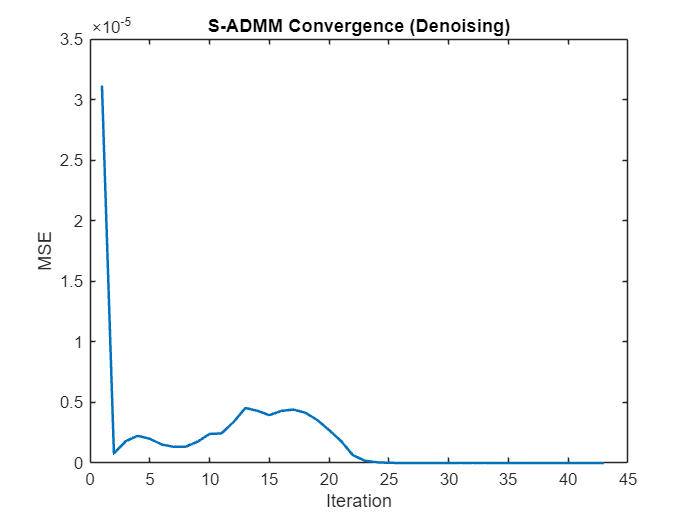

%% S-ADMM Function for Denoising (with gamma tracking)
function [Z, X, hist] = sadmm(D, lambda, gamma0, rho, maxIter, tol)
    [m, n] = size(D);
    X = zeros(m, n); Z = zeros(m, n); Y = zeros(m, n); gamma = gamma0;

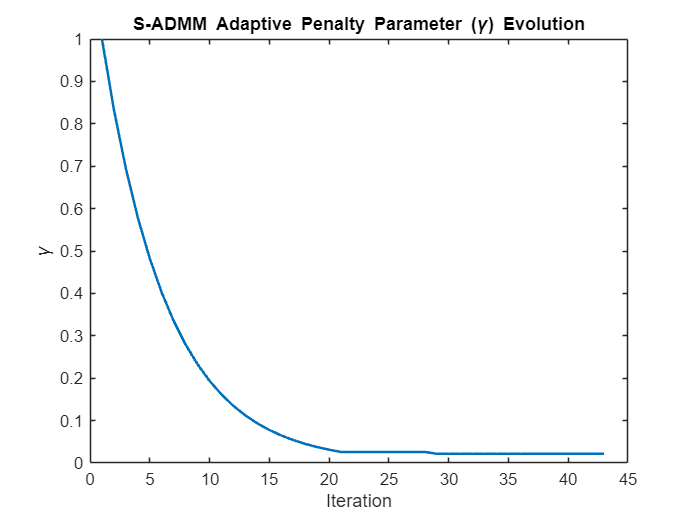

    hist.mse = zeros(maxIter, 1);
    hist.gamma = zeros(maxIter, 1); % Track gamma
    for k = 1:maxIter
        A = D - X + (Y / gamma);
        Z_new = svt(A, 1.0 / gamma);
        B = D - Z_new + (Y / gamma);

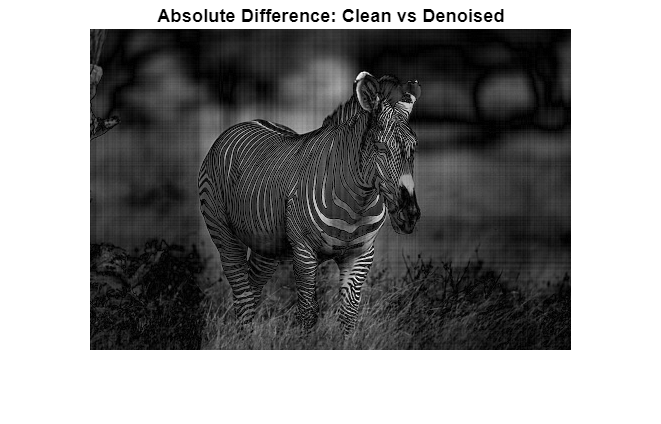

        X_new = col_shrink_21(B, lambda / gamma);
        Y_new = Y + gamma * (D - Z_new - X_new);
        err = norm((Z_new + X_new) - D, 'fro')^2 / (m*n);
        hist.mse(k) = err;
        hist.gamma(k) = gamma; % Save gamma value


        num = norm(Y-Y_new, 'fro');
        den = gamma * (norm(X-X_new, 'fro')+eps);
        ratio = num/den;
        if ratio > 1+rho
            gamma = (1+rho)*gamma;
        elseif ratio < 1/(1+rho)
            gamma = gamma/(1+rho);
        end
        delta = norm(Z_new-Z, 'fro') + norm(X_new-X, 'fro');
        Z = Z_new; X = X_new; Y = Y_new;
        if delta < tol
            hist.mse = hist.mse(1:k);
            hist.gamma = hist.gamma(1:k);

S-ADMM MSE: 0.029658


            break;
        end
    end

S-ADMM PSNR: 15.28 dB


end

7.Runs the S-ADMM function using the noisy image.

`Z_denoised`: final clean image output.

`X_sparse`: estimated noise part.

`hist`: records MSE and gamma evolution.

%% Apply S-ADMM Denoising
[Z_denoised, X_sparse, hist] = sadmm(D, lambda, gamma0, rho, maxIter, tol);

S-ADMM SSIM: 0.5040


8.Visualize Results

-Shows the clean (denoised) image and noise part separately.

`-mat2gray` rescales values to `[0,1]` for proper display.

-Plots how the mean squared error changes over iterations.

-Used to visualize convergence — a decreasing curve means progress.

-Shows how `gamma` changed during iterations.

-Helps see if the adaptive mechanism is stable or oscillating.

-Computes absolute pixelwise error between denoised and original image.

-Displays where the algorithm changed the image most.

%% Visualize Results
figure;
imshow(mat2gray(Z_denoised));
title('Recovered Clean Image (Low-rank part, S-ADMM)');

figure;
imshow(mat2gray(X_sparse));
title('Recovered Sparse Noise (S-ADMM)');

%% Plot Convergence (MSE)
figure;
plot(hist.mse, 'LineWidth', 1.5);
xlabel('Iteration'); ylabel('MSE');
title('S-ADMM Convergence (Denoising)');

%% Plot Evolution of Adaptive Gamma
figure;
plot(hist.gamma, 'LineWidth', 1.5);
xlabel('Iteration'); ylabel('\gamma');
title('S-ADMM Adaptive Penalty Parameter (\gamma) Evolution');

%% Compare with Original/Clean
diff = abs(Z_denoised - I_gray);
figure;
imshow(mat2gray(diff));
title('Absolute Difference: Clean vs Denoised');


9.Computes three standard image-quality metrics:

`mse_val`: average squared error per pixel (lower is better). Calculated directly from the vectors.

`psnr_val`: Peak Signal-to-Noise Ratio (higher is better). 

`ssim_val`: Structural Similarity Index (best = 1). 


%% Quantitative Metrics (MSE, PSNR, SSIM)
mse_val = mean((I_gray(:) - Z_denoised(:)).^2);
disp(['S-ADMM MSE: ', num2str(mse_val, '%.6f')]);

psnr_val = psnr(Z_denoised, I_gray);     % Requires Image Processing Toolbox
disp(['S-ADMM PSNR: ', num2str(psnr_val, '%.2f'), ' dB']);

ssim_val = ssim(Z_denoised, I_gray);     % Requires Image Processing Toolbox
disp(['S-ADMM SSIM: ', num2str(ssim_val, '%.4f')]);
